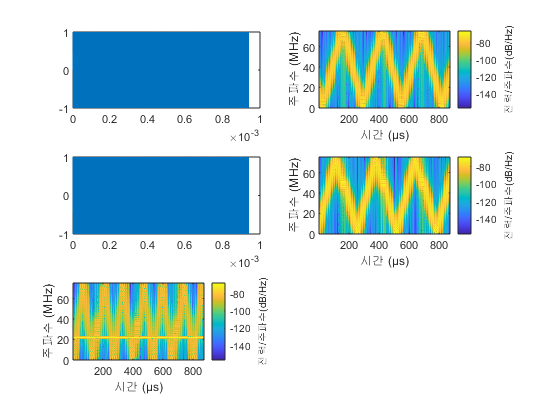

clear all
clc;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% User Defined Range and Velocity of target
R=150; %initial distance of the target
v=50; %speed of the target (give some value between 0 and 10)
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
R_max = 200;
c=3e8; %speed of light
Swp_Tm = 5.5*range2time(R_max,c);
Fs=150e6;
fc=77e9; %carrier freq
BW=150e6; %sweep freq
Slope=BW/Swp_Tm; %sweep rate
D=128; % #of doppler cells OR #of sent periods           % number of chirps
N=2^10; %for length of time
t=linspace(0,D*Swp_Tm,D*N); %total time
n=0;
Dcells_T=length(t)/D; %length of one period
Tx=zeros(1,length(t)); %transmitted signal
Rx=zeros(1,length(t)); %received signal
r_t=zeros(1,length(t));
td=zeros(1,length(t));
for i=1:length(t)
    r_t(i)=R+(v*t(i)); % range of the target in terms of its velocity and initial range
    td(i)= 2*r_t(i)/c; % delay for received signal
    if i>n*Dcells_T && i<=(n+1)*Dcells_T % doing this for D of periods (nt length of pulse)
        Tx(i)=sin(2*pi*(fc*t(i)+.5*Slope*t(i)^2-Slope*t(i)*n*Swp_Tm)); %transmitted signal
        Rx(i)=sin(2*pi*(fc*(t(i)-td(i))+.5*Slope*(t(i)-td(i))^2-Slope*(t(i)-td(i))*n*Swp_Tm)); %received signal
    else
        n=n+1;
        Tx(i)=sin(2*pi*(fc*t(i)+.5*Slope*t(i)^2-Slope*t(i)*n*Swp_Tm)); %transmitted signal
        Rx(i)=sin(2*pi*(fc*(t(i)-td(i))+.5*Slope*(t(i)-td(i))^2-Slope*(t(i)-td(i))*n*Swp_Tm)); %received signal
    end
end
figure ('Name','Transmitted, Received and Beat Signals');
subplot(3,2,1);
plot(t,Tx);
subplot(3,2,2);
spectrogram(Tx,256,250,256,Fs,'yaxis');
subplot(3,2,3);
plot(t,Rx);
subplot(3,2,4);
spectrogram(Rx,256,250,256,Fs,'yaxis');
mixer=(Tx.*Rx);  % IF
subplot(3,2,5);
spectrogram(mixer,256,250,256,Fs,'yaxis');

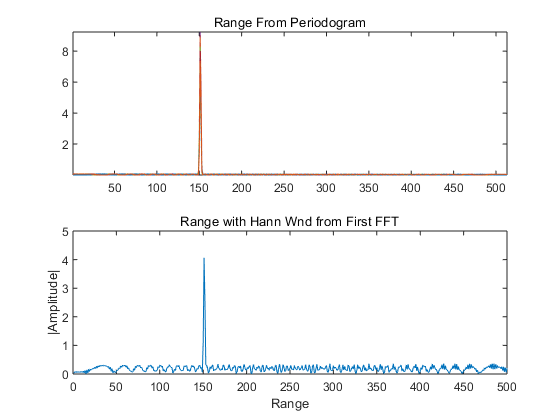

mix1=reshape(mixer,[length(mixer)/D,D]);   
% Row showing range info for one period
% Each column showing number of periods
[My,Ny]=size(mix1');
nfft = 2^nextpow2(Ny);
%Hann_Wnd = mix1.*hamming(Ny);  
Hann_Wnd=conj(mix1).*(hamming(Ny)*ones(1,My));         % sidelobe reduction
R_FFT = fft(Hann_Wnd,nfft)/Ny;
Range_FFT2 = abs(R_FFT);
Range_FFT = Range_FFT2 (1:nfft/2+1);
Range_FFT (2:end-1) = 2* Range_FFT(2:end-1);
range = periodogram(Hann_Wnd, hamming(length(Hann_Wnd)));
figure ('Name','Range from First FFT')
subplot(2,1,1)
plot(range);
title ('Range From Periodogram')
axis tight;
subplot(2,1,2)
plot(15*Range_FFT);
axis ([0 500 0 5]); %Zoom in
title('Range with Hann Wnd from First FFT');
xlabel('Range');
ylabel('|Amplitude|');

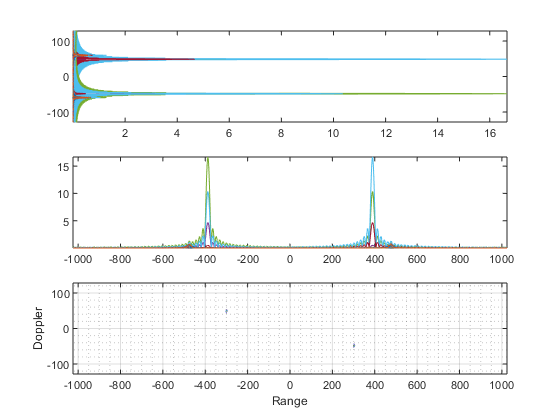

%DOPPLER FROM 2ND FFT
Dop=fftshift(fft(R_FFT',1024));         %Second FFT for Doppler information
[My,Ny]=size(Dop);
Range=linspace(-N,N,Ny);
doppler=linspace(-D,D,My);
figure ('Name','Range and Doppler after 2nd FFT');
subplot(3,1,1)
plot(abs(Dop),doppler);
axis tight;
subplot(3,1,2)
plot(Range,abs(Dop));
axis tight;
subplot(3,1,3);
contour(Range,doppler,abs(Dop));
axis tight;
% xlim ([0 300])
% ylim ([-200 0])
grid on;
xlabel('Range');
ylabel('Doppler')
grid minor;